# Control statements: How to use the `while`** loop**?

## Introduction

So far, while writing MATLAB Live Scripts, we’ve been writing commands to be executed one line after another. Unless a line is a comment (denoted by a preceding "`%`"), every line in a script will be executed in order of appearance (sequentially). For example:

x = linspace(0, 1, 100);  %1st, x is a vector of 100 numbers from 0 to 1
y = x.^2 + 1;             %2nd, y is a vector of 100 numbers calculated as x.^2+1
plot(x, y);               %3rd, plots vectors x against y on a graph, and shows it in the Output view
title('Plot of x^2+1');   %4th, adds a title to the plot
xlabel('x');              %5th, adds a label to the x-axis
ylabel('y');              %last, adds a label to the y-axis

Fortunately, in MATLAB Live Scripts we can also make use of **control statements**. These are statements (commands) that will allow you to have total control over the **flow** of the code being executed – maybe you only want particular lines executed in particular situations? Or want to repeat a command over and over again?

The flow of the program (live script) can be changed from just executing lines one-by-one, to skipping or repeating intermediate sets of commands.

More technically, control statements are used to modify the order in which commands are executed by MATLAB, so that we are not restricted to executing commands sequentially. MATLAB provides several types of control statements, including

- [if statements](https://au.mathworks.com/help/matlab/ref/if.html), which execute a set of commands if a given condition is satisfied;

- [for loops](https://au.mathworks.com/help/matlab/ref/for.html), which execute a set of commands a given number of times; and

- [while loops](https://au.mathworks.com/help/matlab/ref/while.html), which execute a set of commands while a given condition is true.

In this activity we will learn the basics about how to use `while` loops.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, *click into the code section* and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

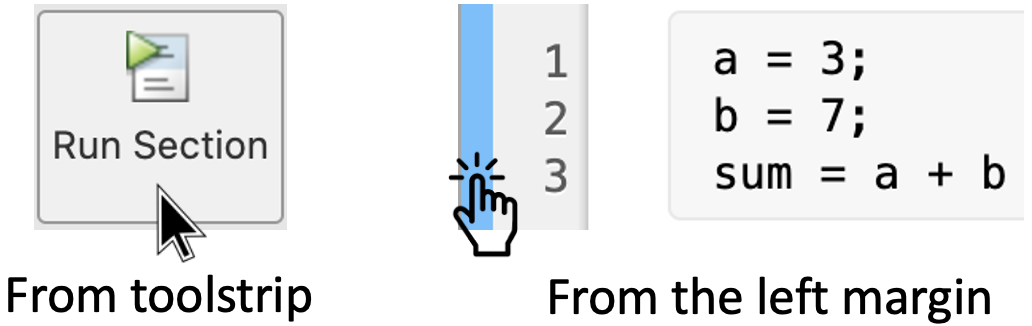

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. The `while` loop

A `while` loop has the following general form:

When executed, if the condition is true, then the commands inside the loop (i.e., before the `end` command) are executed and the loop is executed again; if the condition is false, then MATLAB exits the loop, without executing the commands inside the loop, and moves on to the next line after the `end` command. 

Unlike `for` loops, which run for a pre-determined number of iterations, `while` loops can continue indefinitely so long as their condition is unmet. This could be very useful when a number of iterations is not known beforehand, such as when you want to continue to evaluate some expression until there is convergence, for example, or until you reach a certain state.

Let's see some examples to learn how the `while` loop works.

### 1.1 Basic use

#### Example 1:

Consider the following `while` loop:

n = 0;          % Define a variable "n" equal to 1
  
while n < 4     % Set the condition
   
    n = n + 1   % Assign a new value to "n"
   
end             % Exit the "while" loop

For this example, the condition is `n < 3`, which determines if the variable `n` is less than `3`, and there is a single command inside the body of the loop which adds `1` to `n` and displays the result in the command window (since it is not followed by a semicolon). When the loop is executed, the variable `n` is initially set equal to 0. Then, while the variable `n` is less than `4`, the command `n = n + 1` is repeatedly executed, incrementing `n` by 1 each time and displaying the result in the command window. Eventually, the condition `n < 4` will no longer hold since the value of `n` is always increasing. For the first value of `n` such that the condition fails, `n = 4`, MATLAB exits the `while` loop. Thus, the following output is produced in the Output view.

#### Example 2: 

Now let's say that we want to put some money in the bank and subject to a yearly interest rate we want to see how long it will take until we reach a million dollars and can retire. So, for example, if we start with an initial balance of $5000, a yearly interest rate of 8%, and we deposit $4000 at the beginning of every year, how long does it take to reach a million dollars? To answer this question, we can use a while loop as follows:

bal = 5000;                 % Starting balance
year = 0;                   % We start off at year 0

while bal < 1000000         % Set the condition: "bal" is less than one million

    bal = 1.08*bal + 4000;  % Interest rate 8% plus 4000 deposit at the beginning of

    year = year + 1;        % Increase the year

end                         % Exit "while" loop.

year                        % Display years
bal                         % Display balance accumulated

When executed, the variables `bal` and `year` are initially set equal to `5000` and `0,` respectively. Then, while `bal` is less than `1000000`, first the expression

`bal = 1.08*bal + 4000;`

means that `bal` will be set equal to 8% interest times the previous balance adding up the yearly deposit of $4000. Then we increment `year` by one to count how many years it will take because unlike a `for` loop nothing is incrementing automatically. For the first value of `bal` such that the condition fails, MATLAB exits the `while` loop and displays the final balance and the number of years.

### 1.2 Logical operators

In the `while` loop you can use relational operators (such as `<` or `==`) and also logical operators (such as `&&`, `||`, or `~`). Use the logical operators "`and`" and "`or`" to create compound expressions. Or in other words, to combine different conditions. MATLAB evaluates these conditions from left to right, following the rules prescribed by the [logical operators](https://au.mathworks.com/help/matlab/logical-operations.html).

#### Example 3:

For instance, let's calculate the smallest even integer that is divisible by 13 and whose square root is greater than 6.

x = 0;                                   % Set an initial variable "x" as 0.

while (rem(x,13) ~= 0) || (sqrt(x) < 6)  % Set condition.

    x = x + 2;                           % Increase variable by 2.

end                                      % End "while" loop

fprintf('The required number is %d',x);

**Remark:** We used the command [`rem(a,b)`](https://au.mathworks.com/help/matlab/ref/rem.html) to determine the *remainder* `r` after the division of `a` by `b`. If `r = 0`, this means that `a` is divisible by `b`.

When executed, the variable `x` is initially set equal to `0`. Then, while 

`rem(x,13) ~= 0` or `sqrt(x) < 6`

is true the command `x = x + 2 `is repeatedly executed, incrementing `x` by `2` each time. At some point, the condition will be false since the value of `x` is increasing. In this case, the first value of `x` such that the condition fails is x = 52. Then MATLAB exits the `while` loop and prints this value with the help of the command [`fprintf()`](https://au.mathworks.com/help/matlab/ref/fprintf.html).

### 1.3 Using `while` loops as `for` loops

`While` loops can also be used just like `for` loops. For instance, the following code calculates the sum of an array (or vector) using a `for` loop:

x = 1:10;                % Define array of numbers from 1 to 10
sum = 0;                 % Initial value of the "sum"
for i = 1:length(x)      % For every element in "x"
    sum = sum + x(i)     % 
end


Run this section and you will see the value of sum updated in every iteration. If you prefer to display only the final result just add the semicolon  "`;`", that is:

`sum = sum + x(i);`

Then write the variable `sum` outside the `for` loop, right after the `end` command. Try it and re-run this section to see the result!

In a `for` loop we have a counter that changes automatically on every loop iteration; however we can emulate this using `while` loop as follows:

a = 1:10;                       % Define array of numbers "a" from 1 to 10
sum_a = 0;                      % Initial value of the "sum_a"
counter = 1;                    % Here we need to declare a "counter"
while counter <= length(a)      % Set condition
    sum_a = sum_a + a(counter)  % Assign a new value to sum_a
    counter = counter + 1       % We increase the "counter"
end                             % End "while" loop

Run this section and compare the results with those obtained using a `for` loop. Again, if you prefer to display only the final result just add the semicolon  "`;`", that is:

`sum_a = sum_a + a(counter);`

Then write the variable `sum_a` outside the `for` loop, right after the `end` command. Finally, re-run this section.

Altogether, `for` and `while` loops are an important tool for programming. Although `for` loops make iteration easy, they are not as versatile as `while` loops. `While` loops give you full control over all aspects of the iteration including any indices that you want to increment. They also allow you to have indices that increment non-uniformly but rather depend on conditions of variables in the code. This versatility makes `while` loops an extremely important construct in a programming tool.

### 1.4 Be careful with the infinite loop

When you write a `while` loop, ensure that there will be some point where the condition is false, otherwise the loop will continue running forever (called an infinite loop). 

### **Don't panic!**

If you do happen to execute code that contains an infinite loop, in MATLAB use the keyboard command `Control+C` to stop it. In the Live Script you can **Quit execution** by using the keyboard command `Shift+F5` or click on the **Stop** button from the menu (on the right-side):

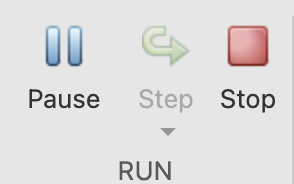

and then **Clear All Output**.

#### Example 4: 

The following is an example of such an *infinite loop:*

n = 1;

while n == 1

    pi

end

Here, the single command inside the loop displays $\pi$ in the Output view but does not alter the value of the variable `n`, which is initially equal to 1. Thus, the condition 

is always true. Consequently, the loop repeatedly displays $\pi$ in the Output view, *ad infinitum *(or at least until you stop it or your computer crashes). Would you like to try it? Run this section to see what happens.

## **2. Hands on practice!**

Let's practice what we just learned.

Recall the Fibonacci sequence is defined recursively as follows:

$F_1 =1,{\;F}_2 =1$ and $F_i =F_{i-1} +F_{i-2}$ for $i>2$.

Thus, for example, $F_3 =2$, $F_4 =3$, $F_5 =5$ and so on.

## Activity

Complete the following code to calculate the *n-*th term of the Fibonacci sequence using a `while` loop:

% Set the n-th term of the Fibonacci sequence to calculate. 
% For example, the 5th term with the variable "n"

n = 5;
     
% 1. Create a row vector called "F" containing n zeros.
% This vector will be used to store the terms of the Fibonacci sequence.

%{--Replace this comment with code--}%

% 2. Define the first two terms of the Fibonacci sequence

%{--Replace this comment with code--}%

% 3. Define a counter "i" starting at 3
%    since we already have the first two values

i = 3;
     
% 4. While i <= n use the recursive formula
%    to calculate F_3, F_4, ... , F_n.
while i <= n
     
    %{--Replace this comment with code--}%
         
end

% 4. Display last value in F.

%{--Replace this comment with code--}%

You can check if your code is correct by comparing the output with the given values.

## Activity 2

We can use `while` loops to easily calculate sum of series with specific conditions.

For example, for what value of $n$ does the summation


$$\sum_{k=1}^n \frac{1}{\sqrt{k}}=\frac{1}{\sqrt{1}}+\frac{1}{\sqrt{2}}+\frac{1}{\sqrt{3}}+\cdots +\frac{1}{\sqrt{n}}$$


first exceed 30? To answer this run this section and analyse the following code with its output.

s = 0;

k = 0;

while s < 30

    k = k + 1;

    s = s + 1/sqrt(k);

end

number_of_terms = k

sum = s

Now write some code to know for what value of $m$ the summation


$$\sum_{i=1}^m \frac{1}{{\left(i+1\right)}^{3/4} }$$


first exceeds 17.

Write your code here: